clear; 
clc;

### Save system data to the workspace.

System data includes:

- System frequency

- Synchronous generators' internal data (reactance, inertia and damping constants).

- Transmission line data (R, X, B values in the  π model).

- Bus specification data (bus type, specified values)

a3_02_systemData;

This system is based on the <a href = "t.ly/2tZ9">WSCC 9-Bus System</a>
(also known as the IEEE 9-Bus System).
System values obtained from <a href= "t.ly/yABF">here</a>.


### Construct the Y_bus matrix from the bus and line data  and save it to the workspace

fprintf(['For the code for Power Flow Analysis,\n',...
    '<a href = "t.ly/3cdE">this MATLAB File Exchange entry</a>\n'...
    'has been referred to.\n']);

For the code for Power Flow Analysis,
<a href = "t.ly/3cdE">this MATLAB File Exchange entry</a>
has been referred to.



a3_03_construct_Y_Bus_matrix;

### Compute the steady state bus voltages and angles via power flow analysis.

a3_04_NRPF;

### Intermediate housekeeping script

- Save the generator voltages, real powers

- Preprocess the **branchData **in a way which will ultimately separate the order of the generators and loads, when the Y_Bus is constructed again.

a3_05_loadAssimilation;

### Construct the reduced bus matrix and save it to the workspace

a3_06_construct_Y_g_matrix;

### Compute generator powers again with the newly constructed reduced bus matrix

a3_07_genPowerComputation;

### Perform transient analysis on the system

a3_08_transientAnalysis

### Plot the results

- Machine internal angle vs time

- Each machine's internal angle is taken with respect to the slack bus internal angle as reference

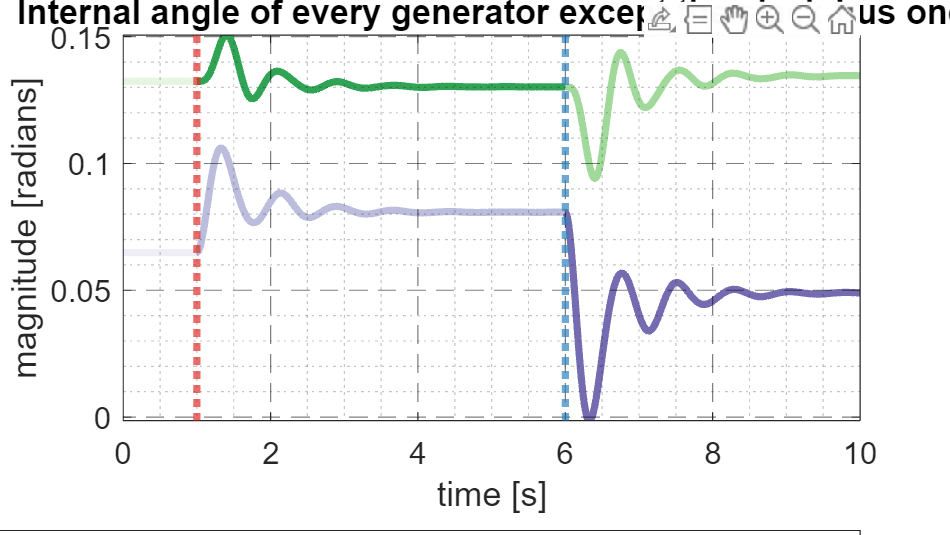

Click here to view a bigger image.


a3_10_plotResults